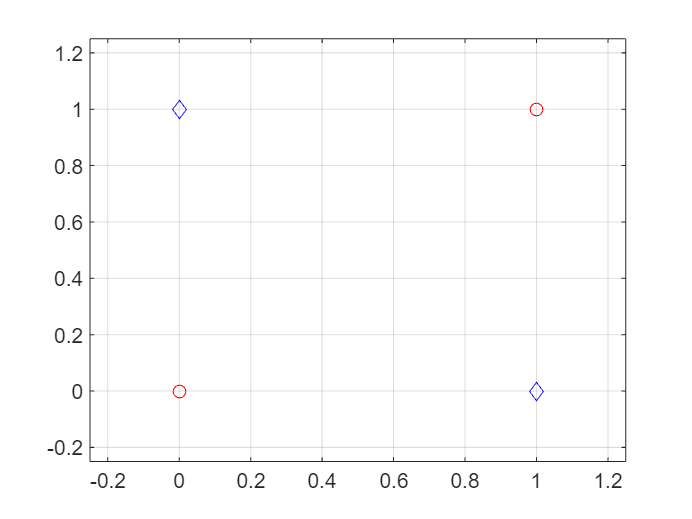

%Single Layer Perceptron

%create the data
X=[[0;0] [0;1] [1;0] [1;1]];
T=[0 1 1 0];

%Plot the data
figure(1)
plot(X(1,1),X(2,1),'ro')
hold on
grid on
plot(X(1,4),X(2,4),'ro')
plot(X(1,2:3),X(2,2:3),'bd')
xlim([-.25,1.25])
ylim([-.25,1.25])

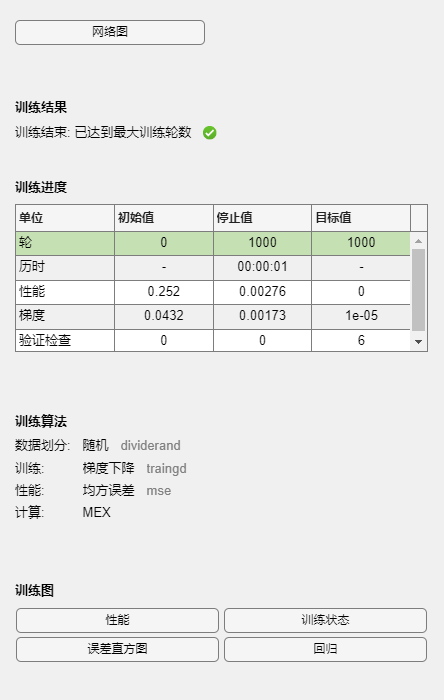


%create a neural network
net=feedforwardnet(2,'traingd');

%configure the neural network
net.divideParam.trainRatio=1;%training set[%]
net.divideParam.valRatio=0;%validation set[%]
net.divideParam.testRatio=0;%test set[%]
net.inputs{1}.processFcns={};%modify the process function for inputs
net.outputs{2}.processFcns={};%modify the process function for outputs
net.layers{1}.transferFcn='logsig';%the transfer function for the first layer
net.layers{2}.transferFcn='logsig';%the transfer function for the second layer
net.trainParam.lr=1;%learning rate

%train
net=train(net,X,T);


y=net([0;0]);
Y=net(X)

Y =     0.0541    0.9458    0.9463    0.0479
